## Module one project 6

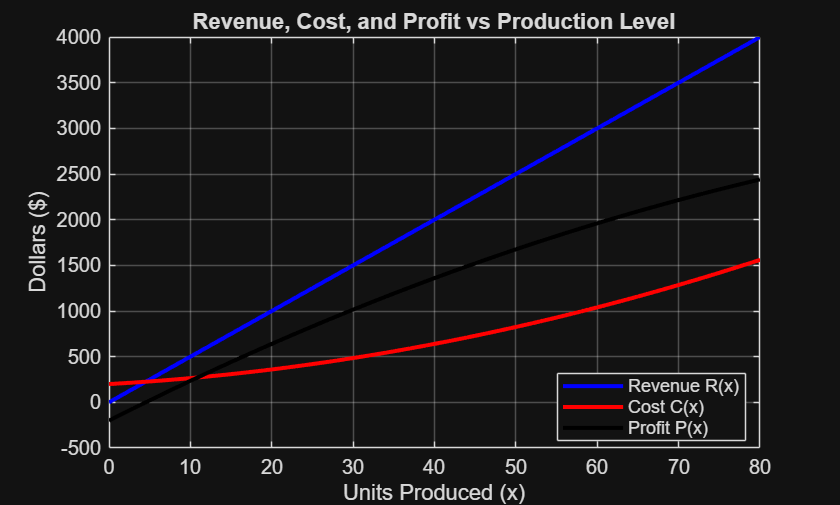

%% Project 6: Profit vs Production (Linear + Quadratic Comparison)
clear; clc; close all;

%% -------------------------------------------------------------
% 1. Choose realistic economic parameters
% -------------------------------------------------------------
p = 50;        % selling price per unit ($/unit)
a = 0.15;      % quadratic cost coefficient (increasing marginal cost)
b = 5;         % linear cost coefficient
c = 200;       % fixed cost ($)

% Production range
x = 0:1:80;    % units produced

%% -------------------------------------------------------------
% 2. Compute Revenue, Cost, and Profit
% -------------------------------------------------------------
R = p .* x;                     % revenue function R(x) = p*x
C = a .* x.^2 + b .* x + c;     % cost function C(x) = ax^2 + bx + c
P = R - C;                      % profit function P(x)

%% -------------------------------------------------------------
% 3. Plot R(x), C(x), and P(x)
% -------------------------------------------------------------
figure;
plot(x, R, 'b', 'LineWidth', 2); hold on;
plot(x, C, 'r', 'LineWidth', 2);
plot(x, P, 'k', 'LineWidth', 2);
grid on;

xlabel('Units Produced (x)');
ylabel('Dollars ($)');
title('Revenue, Cost, and Profit vs Production Level');
legend('Revenue R(x)', 'Cost C(x)', 'Profit P(x)', 'Location', 'best');


%% -------------------------------------------------------------
% 4. Identify production level that maximizes profit
% -------------------------------------------------------------
[profitMax, idxMax] = max(P);
x_maxProfit = x(idxMax);

fprintf('Maximum profit = $%.2f at x = %d units\n', profitMax, x_maxProfit);

Maximum profit = $2440.00 at x = 80 units



%% -------------------------------------------------------------
% 5. Find break-even points where P(x) = 0
% -------------------------------------------------------------
% Break-even occurs when profit changes sign
signChangeIdx = find(P(1:end-1) .* P(2:end) < 0);

breakEvenPoints = [];

for i = 1:length(signChangeIdx)
    % Linear interpolation between points where sign flips
    x1 = x(signChangeIdx(i));
    x2 = x(signChangeIdx(i)+1);
    P1 = P(signChangeIdx(i));
    P2 = P(signChangeIdx(i)+1);

    x_zero = x1 - P1 * (x2 - x1) / (P2 - P1);
    breakEvenPoints(end+1) = x_zero;
end

% Display break-even points
if isempty(breakEvenPoints)
    fprintf('No break-even points exist for this model.\n');
else
    fprintf('Break-even points occur at x ≈ %.2f and x ≈ %.2f units\n', breakEvenPoints);
end

Break-even points occur at x ≈ 4.51 and x ≈ 